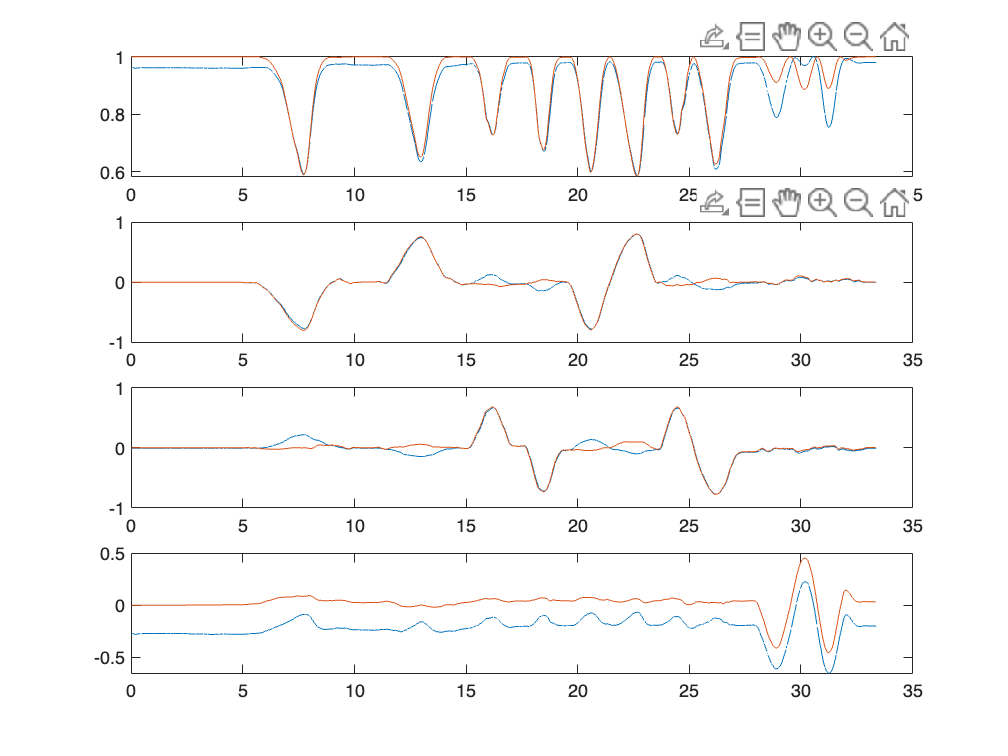

clear;

load('data_29_may_task_4_with_orientation.mat');


t0 = [];  % Initial time (initialize on first data received)
nx = 10;   % Assuming that you use q as state variable.
% Add your filter settings here.

% Current filter state.
x = [1; 0; 0; 0;
     0; 0; 0;
     0; 0; 0];

q0 = [1; 0; 0; 0];
x = [q0; zeros(3,1); zeros(3,1)];
P = diag([0.1*ones(1,4), 0.01*ones(1,3), 0.01*ones(1,3)]);

% Saved filter states.
xhat = struct('t', zeros(1, 0),...
              'x', zeros(nx, 0),...
              'P', zeros(nx, nx, 0));

DataLength = size(meas.gyr, 2);

prev_t = meas.t(1);

for i = 1:DataLength
    if isnan(meas.gyr(1, i))  % No new data received
        continue;        % Skips the rest of the look
    end

    t = meas.t(i);
    if isempty(t0)  % Initialize t0
      t0 = t;
    end

    % acceleration
    % acc = data(1, 2:4)';
    % if ~any(isnan(acc))  % Acc measurements are available.
    %     % Do something
    % end

    % mag = data(1, 8:10)';
    % if ~any(isnan(mag))  % Mag measurements are available.
    %     % Do something
    % end

    % gyro
    gyro_k = meas.gyr(:, i);
    if ~any(isnan(gyro_k))  % Gyro measurements are available.

        t = meas.t(i);
        T = t - prev_t;
        prev_t = t;

        gyro_noise = 1e-5;
        bias_omega_noise = 1e-7;
        bias_acc_noise = 1e-6;
        Rw = diag([gyro_noise*ones(1,3), bias_omega_noise*ones(1,3), bias_acc_noise*ones(1,3)]);
        
        [x, P] = tu_qw(x, P, gyro_k, T, Rw);
    end
    
    orientation = meas.orient(:, i);

    xhat.x(:, end+1) = x;
    xhat.P(:, :, end+1) = P;
    xhat.t(end+1) = t - t0;
end


figure;

for i =1:4
    subplot(4, 1, i);
    plot(meas.t, meas.orient(i, :)); hold on;
    plot(xhat.t, xhat.x(i, :)); hold on;
end